# Numerical and logical indexing

In this exercise you will learn how to access signal amplitude values in different ways. Either the position of the sample or its sampling time is used to get the amplitude value. You will experiment with both 1D and 2D signals, as well as with grayscale and color images.

Note: the topics of this exercise are in the [MATLAB Onramp tutorial](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), too. Students that already completed the tutorial can skip this exercise.

Some of the functions used in this livescript require the Image processing Toolbox™. If this support package is not installed, the functions provide the download link.

% Clear workspace and command window
clear;
clc;

## 1D signals

### Toy example: the ramp signal

Generate a simple ramp signal x(n) = n;

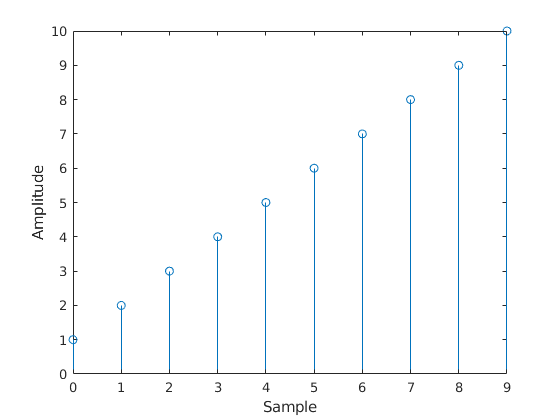

clear;clc;
D = 10;         % number of samples
n = 1:D;        % simulated time axis array
signal = 1:D;   % amplitude array

% Visualization
figure;
stem(n, signal);
xlabel('Sample');
ylabel('Amplitude');

### Positional indexing

Get the amplitude of the signal at a specific position.

index =1; % define the index to pick
if index <= length(signal)
    % If the index is within the signal, pick it
    fprintf('Sample at position %d:\n', index);
    disp(signal(index)); % indexing
else
    % Otherwise, warn the user
    fprintf('Index %d out of range for signal of length %d.\n', index, length(signal));
end

Sample at position 1:


     1



### Logical indexing using the time axis

Get the amplitude of the signal at a specific time.

n1 =0; % define the time to pick
if any(n == n1)
    % If the time is within the signal, pick it
    logical_index = false(size(signal)); % define a boolean vector
    logical_index(n == n1) = true;       % set the selected time
    fprintf('Sample at n=%f:\n', n1);
    disp(signal(logical_index));         % indexing
else
    % Otherwise, warn the user
    fprintf('No samples at %f\n', n1);
end

Sample at n=0.000000 sec.:


     1



### Multiple indexing

Example using multiple indexes to access the signal.

% Numerical indexing
indexes = [1,3,5];
% Logical indexing
n3 = [1,3,5];
logical_indexes = false(size(signal));  % define a boolean vector
logical_indexes(ismember(n,n3)) = true; % set all the selected times

fprintf('\nSample at positions [%d,%d,%d]:\n', indexes(1),indexes(2),indexes(3));


Sample at positions [1,3,5]:


disp(signal(indexes));          % indexing

     1     3     5



fprintf('Sample at n=[%f,%f,%f]:\n', n3(1),n3(2),n3(3));

Sample at n=[1.000000,3.000000,5.000000] sec.:


disp(signal(logical_indexes));  % indexing

     2     4     6



## 2D signals

### Toy example: a 3x3 matrix

Reshape a vector to obtain a 3x3 matrix.

D2 = 3;                             % duration in number of samples along each dimension
signal2 = reshape(1:D2*D2,D2,D2);   % 2D signal by reshaping a vector
fprintf('\n2D signal\n');


2D signal


disp(signal2);                      % print the matrix of amplitude values

     1     4     7
     2     5     8
     3     6     9



### Visualization

Visualization of the matrix as an image: amplitude values are color-coded.

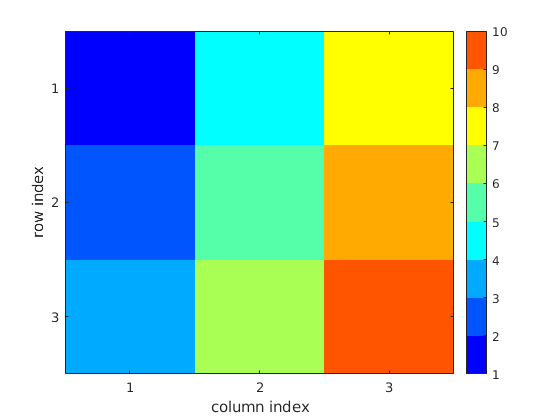

figure;
image(signal2);
colormap(jet(D2*D2));
colorbar; % see the color bar for amplitude values
ylabel('row index');
xlabel('column index');
yticks(1:D2);
xticks(1:D2);

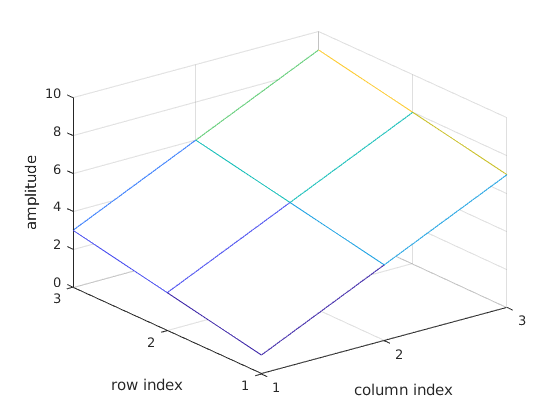


% Visualization as 3D mesh: amplitude values are reported on the z axis
[col_mesh, row_mesh] = meshgrid(1:D2, 1:D2); % define the mesh's x and y axes
figure;
mesh(col_mesh, row_mesh, signal2);   % see z axis for amplitude values
ylabel('row index');
xlabel('column index');
zlabel('amplitude');
yticks(1:D2);xticks(1:D2);

### Indexes and subscripts

Signals with multiple dimensions can be accessed with linear indexes or by means of subscripts.

% Numerical indexing with single index
% The access order is row-wise
index =5;
if index <= numel(signal2)
    % If the index is within the signal, pick it
    fprintf('Sample at position %d:\n', index);
    disp(signal2(index)); % indexing
else
    % Otherwise, warn the user
    fprintf('Index %d out of range for 2D signal with %d samples.\n', index, numel(signal));
end

Sample at position 5:


     5




% Numerical indexing with subscripts
row =2;
col =2;
if row <= size(signal2, 1) && col <= size(signal2, 2)
    % If both the subscripts are within the signal, pick it
    fprintf('Sample at position (%d,%d):\n', row, col);
    disp(signal2(row,col)); % indexing
elseif row > size(signal2, 1)
    % If the row subscript is out of the signal, warn the user
    fprintf('Row index %d out of range for signal of size %dx%d.\n', row, size(signal,1), size(signal,2));
elseif col > size(signal2, 2)
    % If the column subscript is out of the signal, warn the user
    fprintf('Column index %d out of range for signal of size %dx%d.\n', col, size(signal,1), size(signal,2));
end

Sample at position (2,2):


     5



### Multiple indexing

Example using multiple indexes to access the 2D signal.

indexes = [1,3,7,9]; % set the indexes
fprintf('\nSample at positions [%d,%d,%d,%d]:\n', indexes(1),indexes(2),indexes(3),indexes(4));


Sample at positions [1,3,7,9]:


disp(signal2(indexes)); % indexing

     1     3     7     9




rows = [1,3];        % set the row subscripts
cols = [1,3];        % set the column subscripts
fprintf('\nSample at rows [%d,%d] and cols [%d,%d]:\n', rows(1),rows(2),cols(1),cols(2));


Sample at rows [1,3] and cols [1,3]:


disp(signal2(rows,cols)); % indexing

     1     7
     3     9



Note:

Depending on how the 2D signal is indexed, the returned samples are either a 2D sub-matrix or a flattened vector.

Exercise:

Access to a 2D/3D signal using logical indexing. What is the shape of the returned samples?

## Images

### Grayscale images as 2D signals

Grayscale images are matrices. Each element, the pixel, is a number that represents a gray tone.

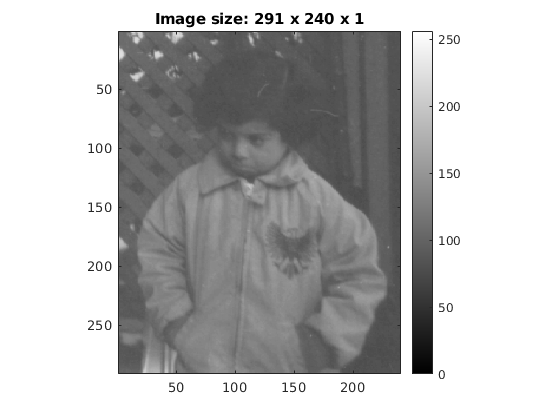

% Read the image file and decode it
im1 = imread('pout.tif');

% Visualization
figure;
image(im1);
axis image;
colormap(gray(256));
colorbar;
title(sprintf('Image size: %d x %d x %d', size(im1,1), size(im1,2), size(im1,3)));

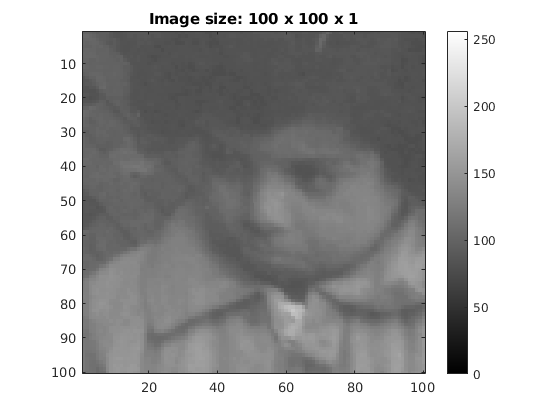


% Sub-matrix extraction
im1_crop = im1(51:150, 51:150);

% Visualization
figure;
image(im1_crop);
axis image;
colormap(gray(256));
colorbar;
title(sprintf('Image size: %d x %d x %d', size(im1_crop,1), size(im1_crop,2), size(im1_crop,3)));

### Color images as 3D signals

Color images are made by 3 equal-size matrices representing color components: red, green, and blue.

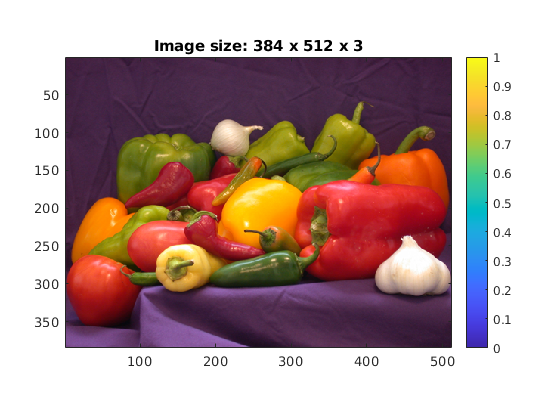

% Read the color image file and decode it
im3 = imread('peppers.png');

% Visualization
figure;
image(im3);
axis image;
colorbar;
title(sprintf('Image size: %d x %d x %d', size(im3,1), size(im3,2), size(im3,3)));

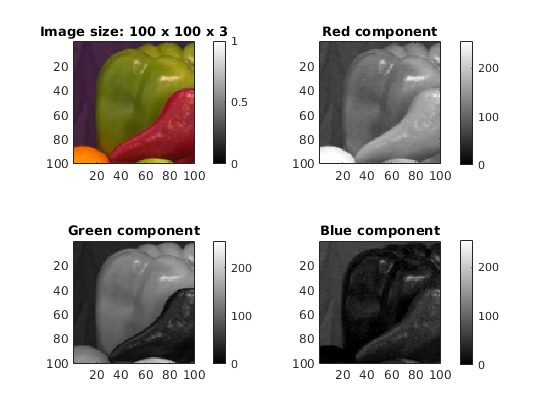


% Sub-matrix extraction
im3_crop       = im3(101:200, 51:150, :); % 3D sub-matrix
im3_crop_red   = im3(101:200, 51:150, 1); % 2D sub-matrix (red component)
im3_crop_green = im3(101:200, 51:150, 2); % 2D sub-matrix (green component)
im3_crop_blue  = im3(101:200, 51:150, 3); % 2D sub-matrix (blue component)

% Visualization
figure;
subplot 221;
image(im3_crop);
axis image;
colorbar;
title(sprintf('Image size: %d x %d x %d', size(im3_crop,1), size(im3_crop,2), size(im3_crop,3)));

subplot 222;
image(im3_crop_red);
axis image;
colormap(gray(256));
colorbar;
title('Red component');

subplot 223;
image(im3_crop_green);
axis image;
colormap(gray(256));
colorbar;
title('Green component');

subplot 224;
image(im3_crop_blue);
axis image;
colormap(gray(256));
colorbar;
title('Blue component');